# Phase-lead compensator to explain phase-leading behavior in *Drosophila* head movements

clear; close all; clc
syms s I c k K_p K_d K_i

## Contol Framework

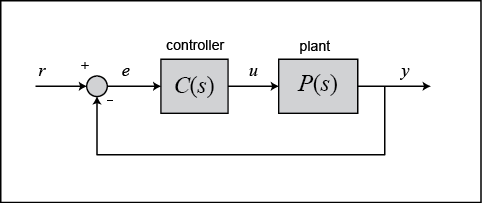

### Plant

P(s) = 1/(I*s^(2) + c*s + k)

$$P(s) = \frac{1}{\text{I}\,s^{2}+c\,s+k}$$

### Controller

C(s) = K_p + K_d*s + K_i*(1/s)

$$C(s) = K_{p}+K_{d}\,s+\frac{K_{i}}{s}$$

### Closed-Loop Model

G(s) = collect(simplify(P(s)*C(s)/(1 + P(s)*C(s))))

$$G(s) = \frac{K_{d}\,s^{2}+K_{p}\,s+K_{i}}{\text{I}\,s^{3}+\left(K_{d}+c\right)\,s^{2}+\left(K_{p}+k\right)\,s+K_{i}}$$

## Plant Paramters

Natural Frequency (rad/s)

wn = 50;

Damping Ratio

z = 1.2;

Head inertia about rotation point (kg*m^2)

I_num = 1;

Head stiffness (N*m/rad)

k_num = wn^(2)*I_num;

Head critical damping (N*m*s/rad)

cc = 2*sqrt(k_num*I_num);

Head damping (N*m*s/rad)

c_num = z*cc;

## Controller Paramters

K = 1000*[2 0.8 0];

## Numeric Model

P_num = simplify(subs(P(s),[I c k],[I_num c_num k_num]))

$$P\_num = \frac{1}{s^{2}+120\,s+2500}$$

C_num = simplify(subs(C(s),[K_p K_d K_i] , K))

$$C\_num = 800\,s+2000$$

G_num = simplify(subs(G(s),[I c k , K_p K_d K_i],[I_num c_num k_num , K]))

$$G\_num = \frac{800\,s+2000}{s^{2}+920\,s+4500}$$

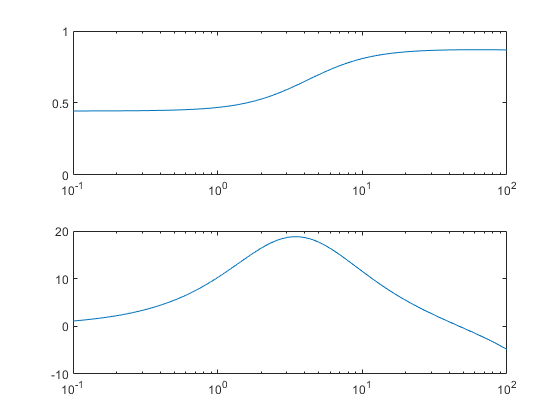

[mag,phase,freq] = bode(sym2tf(G_num),logspace(-1,2,1000));
figure (1) ; clf
ax(1) = subplot(2,1,1);
semilogx(freq,squeeze(mag))
ylim([0 1])
ax(2) = subplot(2,1,2);
semilogx(freq,squeeze(phase))
set(ax,'XLim',10.^[-1 2])

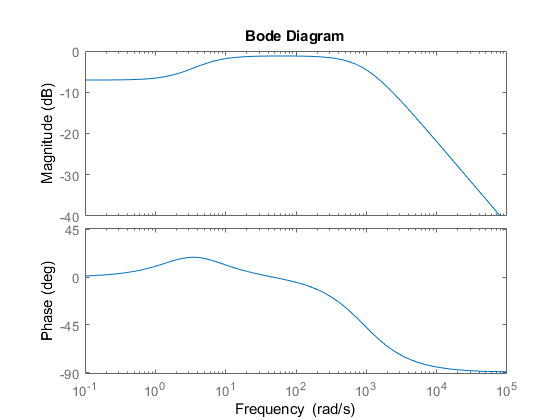


figure (2) ; clf
bode(sym2tf(G_num))